# 05 Conjugate Gradient Methods

🔹 For convex quadratic problems, 

- the steepest descent method is slow in convergence. 

- the Newton’s method is expensive in solving Ax=b. 

- the conjugate gradient method solves Ax=b iteratively. 

🔹Outline 

- Conjugate directions 

- Linear conjugate gradient method 

- Nonlinear conjugate gradient method

## 5.1 THE LINEAR CONJUGATE GRADIENT METHOD

- Among the most useful techniques for** solving large linear systems of equations**. 

- Can be adapted to** solve nonlinear optimization problems**. 

The conjugate gradient method is an iterative method for solving a linear system of equations


$$Ax=b$$


where $A$ is $n\times n$ **symmetric postive definite **matrix. This problem is equivalent to


$$\min \phi(x) := {\frac{1}{2}}x^TAx - b^Tx,$$


We define the ***residual*** of the linear system as

$r(x) := Ax-b = \nabla \phi(x)$, in iteration $k$ it is $r_k := Ax_k-b$

- Solve $Ax=b$ without inverting $A$.

Recall: **Steepest descent+line search**


$$\min \phi(x) := {\frac{1}{2}}x^TAx - b^Tx,$$


- Given an initial guess $x_0$.

- for $k=0,1, \cdots$ search direction: $p_k= -\nabla f_k= -r_k= b -Ax_k$

- The optimal solution $\alpha_k=-\frac{r_k^Tp_k}{p^T_kAp_k}$

- Update $x_{k+1}= x_k + \alpha _kp_k.$ 

#### CONJUGATE DIRECTION METHODS

**Definition: **A set of nonzero vectors $\{p_0, p_1,\cdots, p_l\}$ is said to be **conjugate** with respect to the symmetric positive definite matrix $A$ if 

$p^T_i Ap_j=0, \quad \text{ for all }  i\not= j$             ◼

Remarks

- For a symmetric positive definite matrix $A$, one can define $A$-inner-product as $\langle x, y\rangle _A= x^TAy$.  A-norm is defined as $\|x\|_A=\sqrt{x^TAx}$

- The set $\{p_0, p_1,\cdots, p_l\}$ is orthogonal under $A$-inner-product.

- Any set of vectors satisfying this property is also linearly independent. (Do it)

- we can minimize φ(·) in $n$ steps by successively minimizing it along the individual directions in a conjugate set $\{p_0, p_1,\cdots, p_l\}$

Let's consider ***conjugate direction*** method

- start with $x_0$ and a set of conjugate directions $\{p_0, p_1,\cdots, p_l\}$

- set $x_{k+1}=x_k+\alpha_kp_k$ where $\alpha_k=-\frac{r_k^Tp_k}{p^T_kAp_k}$.

% Example
clearvars
syms alpha x_1 x_2 real
A =[0.25 0;0 1]; b=[1;1];x0 =[0;0]; x= [x_1;x_2];
phi = 0.5*x'*A*x-b'*x

$$phi = \frac{{x_{1}}^{2}}{8}-x_{1}+\frac{{x_{2}}^{2}}{2}-x_{2}$$


f = @(x,y) x.^2/8 - x + y.^2/2-y;
pk = zeros(2,1);
rk = zeros(2,1);
ak =0;
xk=x0;
% steepest descent
for k=1:100
    pk = b-A*x0;
    ak = pk'*pk/(pk'*A*pk);
    xk = x0 +ak*pk;
    if norm(x0-xk)<1e-6, break; end
    x0=xk;
end
xk, k

xk =     4.0000
    1.0000


k = 30


% conjugate directions
pk = eye(2);
rk = zeros(2,1);
ak =0;
xk=x0;
for k = [1:2]
    rk = A*x0 -b;
    ak = -pk(:,k)'*rk/(pk(:,k)'*A*pk(:,k));
    xk=x0+ak*pk(:,k);
    if norm(x0-xk)<1e-6, break; end
    x0=xk;
end
xk

xk =      4
     1


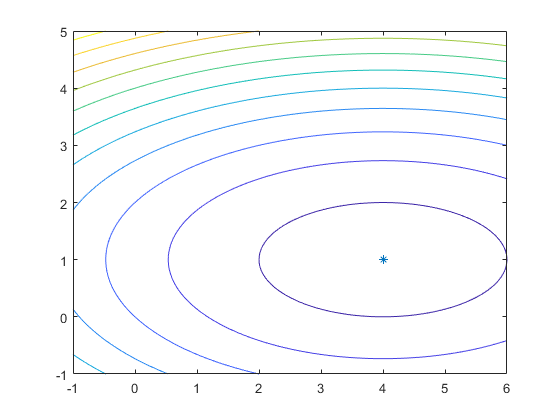

% [X, Y] = meshgrid(linspace(-1,6),linspace(-1,5));
% Z = f(X,Y);
% figure
% contour(X,Y,Z)
% hold on
% plot(4,1,'*')

**Theorem (5.1): **

For any $x_0 \in  \mathbb{R}^n$, the sequence $\{x_k\}$ generated by the conjugate direction algorithm

 $x_{k+1}=x_k+\alpha_kp_k$,  $\alpha_k=-\frac{r_k^Tp_k}{p^T_kAp_k}$  

converges to the solution $x^\ast $ of the linear system $Ax=b$ in at most $n$ steps. 

Proof: (In class)

If $A$ is diagonal

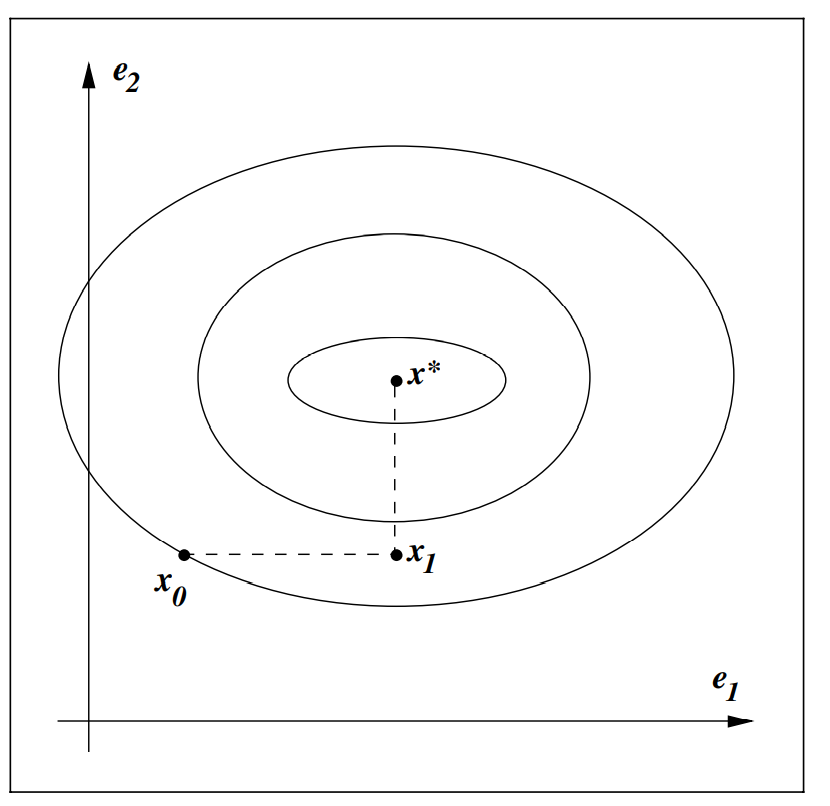

If $A$ is not diagonal

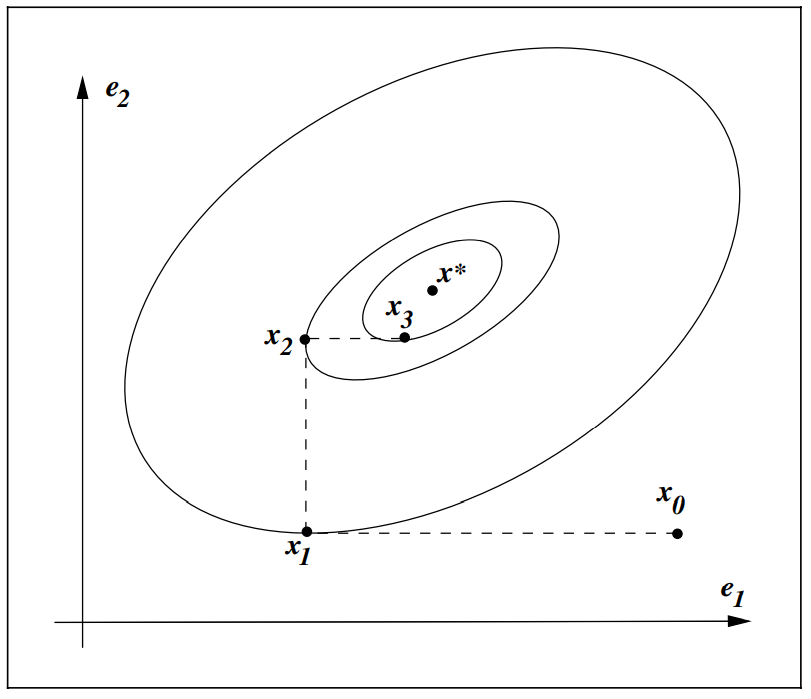

- Let $\hat{x} = S^{-1}x$, $S=[p_0\; p_1\; \cdots\; p_{n-1}]$ where $\{p_0, p_2,..., p_{n-1}\}$ is the set of conjugate directions with respect to A

- $\min \hat{\phi}(\hat{x}) :=\phi(S\hat{x}) ={\frac{1}{2}}\hat{x}^T\left(S^TAS\right)\hat{x} - (S^Tb)^Tx$,

- 
$$r_{k+1} = r_k +\alpha_kAp_k$$


**Theorem 5.2 (Expanding Subspace Minimization).** 

Let $x_0 \in  \mathbb{R}^n$ be any starting point and suppose that the sequence $\{x_k\}$ is generated by the conjugate direction algorithm 

$x_{k+1}=x_k+\alpha_kp_k$,  $\alpha_k=-\frac{r_k^Tp_k}{p^T_kAp_k}$  

Then 


$$r^T_k p_i =  0, \quad \text{ for }  i= 0, 1,..., k - 1,$$


and $x_k$ is the minimizer of $\phi(x)= \frac{1}{2} x^TAx - b^T x$ over the set 


$$\{x | x = x_0 + \text{span}\{p_0, p_1,..., p_{k-1}\}\}.$$


**HOW TO FIND THESE CONJUGATE SET **$\{p_0, p_2,..., p_{n-1}\}$**?**

- eigenvalues of $A$

- Gram–Schmidt 

####  BASIC PROPERTIES OF THE CONJUGATE GRADIENT METHOD

    A better result can be obtained if the current search direction combines the previous one 

    
$$p_{k}= -r_k + \beta _kp_{k-1}$$


    So, in order for $p_k$ and $p_{k-1}$, 


$$\beta_k = \frac{r_kAp_{k-1}}{p_{k-1}^TAp_{k-1}}$$


    and we choose $p_0=-\nabla^T\phi(x_0)=-r_0$.

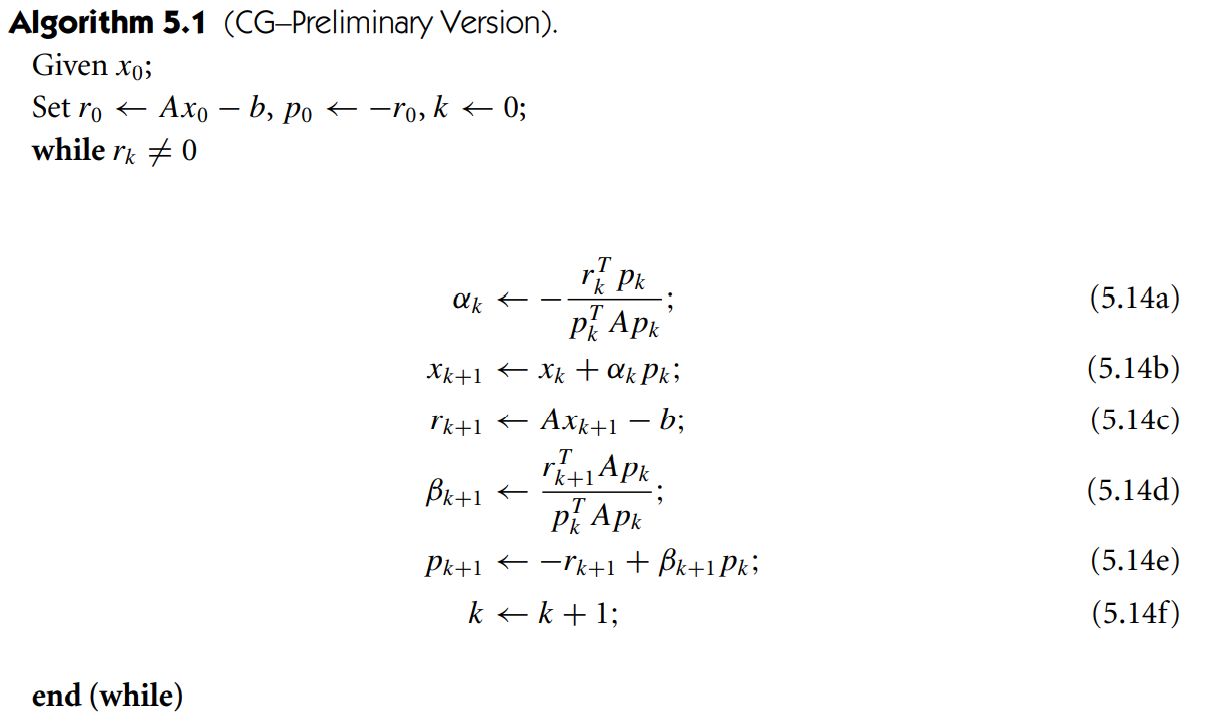

**Definition:** *Krylov subspace of degree* $k$ for $r_0$, is defined as


$$\mathcal{K}(r_0,k)=\text{span}\{r_0, Ar_0, A^2r_0,\dots, A^kr_0 \}$$


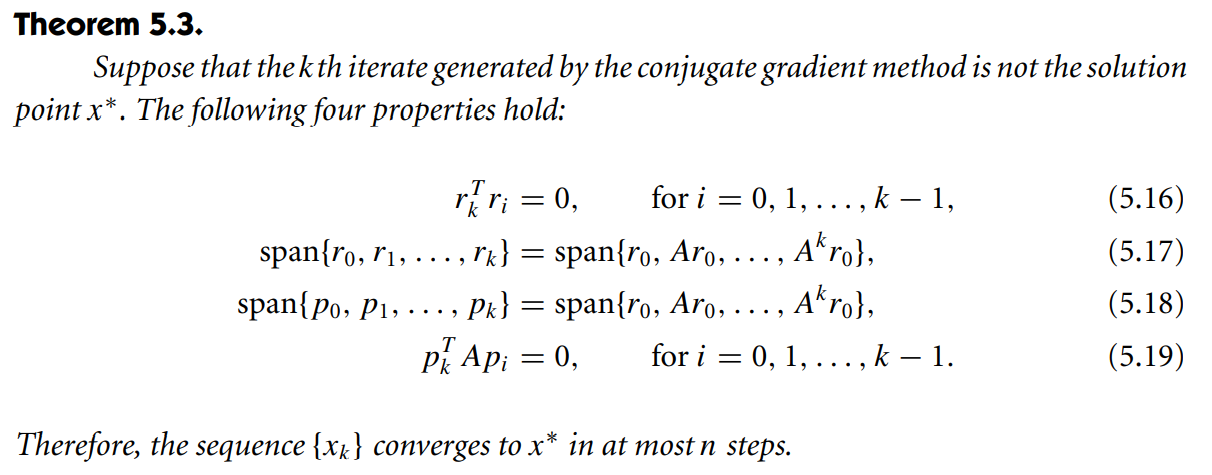

**Remarks:**

- the residuals $r_i$ are mutually orthogonal.

- $r_i$ and $p_k$ belong to the same Krylov space.

- the directions $\{p_0,p_1, \dots, p_{n-1}\}$ are conjugate directions.

####  A PRACTICAL FORM OF THE CONJUGATE GRADIENT METHOD

    We can rewrite

- 
$$\alpha_k=\frac{r^T_kr_k}{p^T_kAp_k}$$


- 
$$\beta_k = \frac{r^T_{k+1}r_{k+1}}{r^T_{k}r_{k}}$$


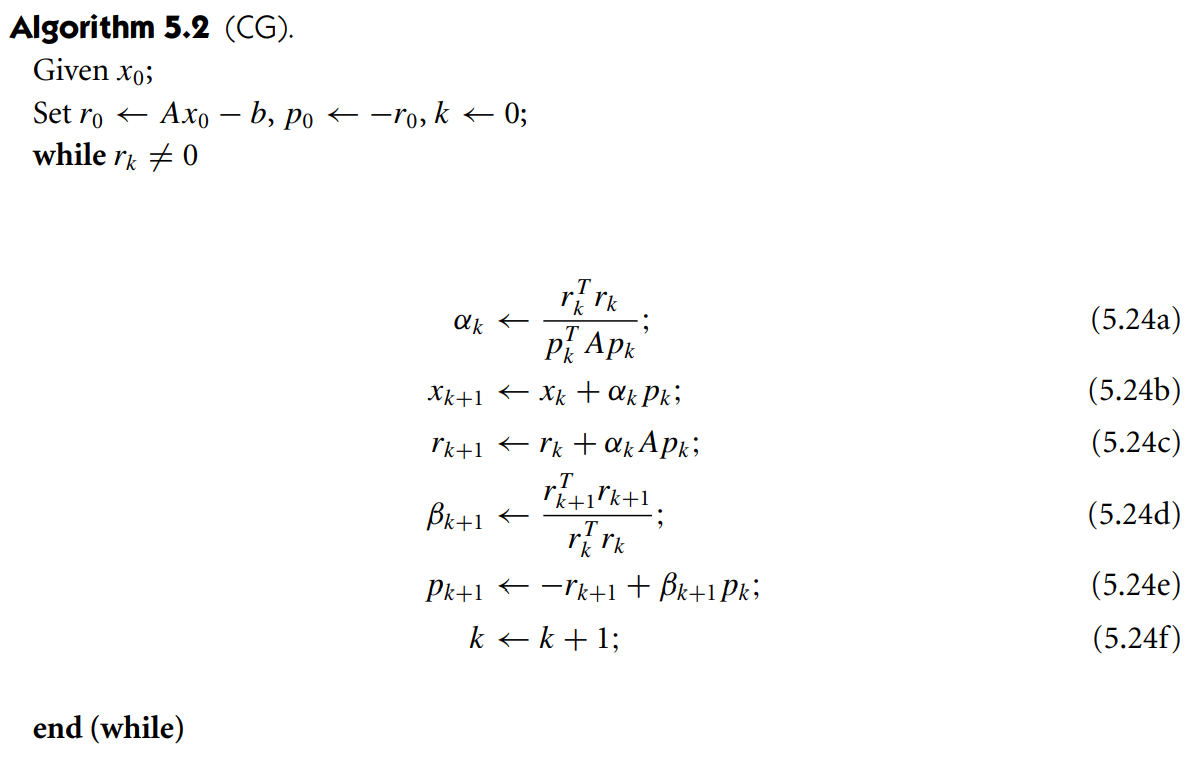

**Remarks:**

- One matrix-vector multiplication per iteration. 

- Only four vectors are required. $(x_k, r_k, p_k)$ 

- Matrix $A$ can be stored implicitly

- CG guarantees convergence in $r$ iterations, where r is the number of distinct eigenvalues of $A$ 

- If $A$ has eigenvalues $\lambda _1 \le  \lambda _2 \le  \dots  \le  \lambda _n,$ 

                 
$$\|x_{k+1} - x^\ast \|^2_A \le  \left(\frac{\lambda_{n-k}-\lambda_1}{\lambda_{n-k}+\lambda_1}\right)^2\|x_0 - x^\ast \|^2_A$$


    RATE OF CONVERGENCE

    PRECONDITIONING

    PRACTICAL PRECONDITIONERS

5.2 NONLINEAR CONJUGATE GRADIENT METHODS

    THE FLETCHER–REEVES METHOD

    THE POLAK–RIBIERE METHOD AND VARIANTS

    QUADRATIC TERMINATION AND RESTARTS

    BEHAVIOR OF THE FLETCHER–REEVES METHOD

    GLOBAL CONVERGENCE

    NUMERICAL PERFORMANCE